# Shakespear vs Trump Dataset

## Setup

clc;
clear all;
close all;
rng(1634256, "twister");

addpath(genpath(fileparts(which(mfilename))));

## Load Data

% Import the data
rawData = parquetread("./datasets/shakespear_trump/shakespear_trump_all-mpnet-base-v2.parquet", "SelectedVariableNames", ["text", "author", "embedding"]);

rawData.author = categorical(rawData.author);

rawData(1:8, :)

ans = 8×3 table
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        

groupcounts(rawData, "author")

ans = 2×3 table
      author      GroupCount    Percent
    __________    __________    _______

    shakespear        472       0.82745
    trump           56571        99.173


## Preperation

sampleSize = 1000;
contamination =0.2;
shakespearIndices = find(rawData.author == "shakespear");
trumpIndices = find(rawData.author == "trump");

numShakespearSamples = round(contamination * sampleSize);
numTrumpSamples = sampleSize - numShakespearSamples;

shakespearSampleIndices = datasample(shakespearIndices, numShakespearSamples, Replace=false);
trumpSampleIndices = datasample(trumpIndices, numTrumpSamples, Replace=false);
data = rawData(sort(cat(1, shakespearSampleIndices, trumpSampleIndices)),:);

clear numShakespearSamples;
clear numTrumpSamples;
clear shakespearSampleIndices;
clear trumpSampleIndices;
clear trumpIndices;
clear shakespearIndices;
clear rawData;

groupcounts(data, "author")

ans = 2×3 table
      author      GroupCount    Percent
    __________    __________    _______

    shakespear       200          20   
    trump            800          80   


unlabeledData = cell2mat(cellfun(@transpose,data.embedding, UniformOutput=false));
centredData = rZscores(unlabeledData);
labels = renamecats(data.author, {'trump' 'shakespear'}, {'inlier' 'outlier'});

## Separability

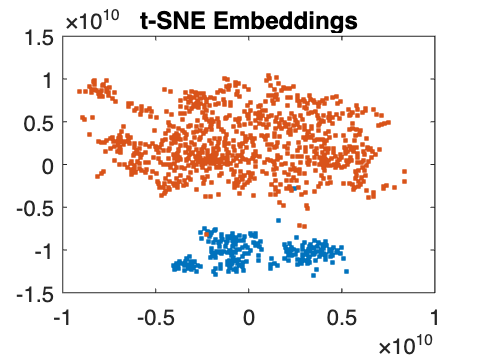

Y = tsne(unlabeledData, Distance="cosine");

figure;
textscatter(Y,data.text,ColorData=labels,TextDensityPercentage=0);
title("t-SNE Embeddings");

clear Y;

separabilityindex(unlabeledData, labels, Distance="cosine")

ans = 0.9990

## Computation

alpha = 0.7;
% kModel = AutoRbfKernel(centredData);
kModel = AutoSphereRbfKernel(unlabeledData);

AutoSphereRbfKernel: Sigma = 1.29649412973073


poc = kMRCD(kModel); 
% solution = poc.runAlgorithm(centredData, alpha);
solution = poc.runAlgorithm(unlabeledData, alpha);

Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SSCM


## Evaluation

hSubset = data(solution.hsubsetIndices, :);

groupcounts(hSubset, "author")

ans = 2×3 table
      author      GroupCount    Percent
    __________    __________    _______

    shakespear        12        1.7143 
    trump            688        98.286 


outliers = data(solution.flaggedOutlierIndices, :);

groupcounts(outliers, "author")

ans = 2×3 table
      author      GroupCount    Percent
    __________    __________    _______

    shakespear       149        88.166 
    trump             20        11.834 


### Confusion Matrix

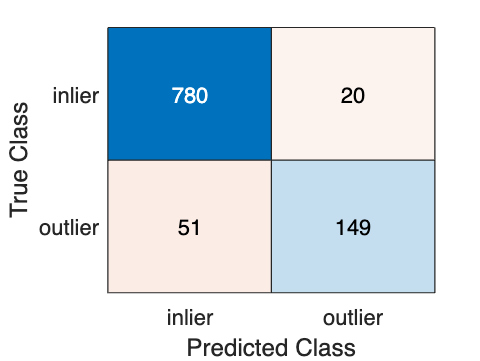

grouphat = categorical(repmat("inlier", size(labels)), categories(labels));
grouphat(solution.flaggedOutlierIndices) = "outlier";

cm = confusionmat(labels,grouphat);
figure;
confusionchart(cm, categories(labels));

struct2table(confusionstats(cm))

ans = 1×5 table
    accuracy    precision    sensitivity    specificity    f1Score
    ________    _________    ___________    ___________    _______

     0.929       0.93863        0.975          0.745       0.95647


### Mahalanobis Distances

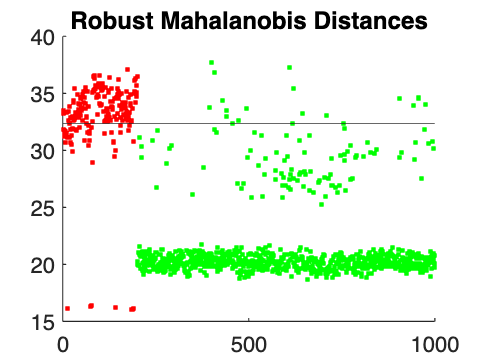

figure;
mahalchart(labels, solution.rd, solution.cutoff);

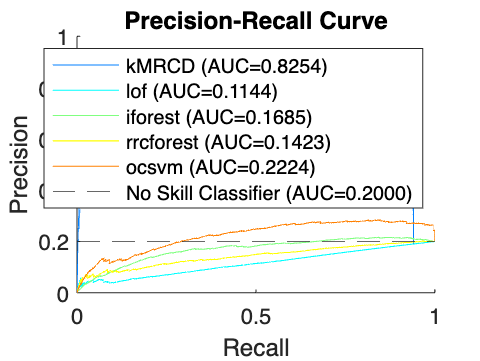

ans = 5×6 table
                 accuracy    precision    sensitivity    specificity    f1Score     aucpr 
                 ________    _________    ___________    ___________    _______    _______

    kMRCD         0.929       0.93863         0.975         0.745       0.95647    0.82542
    lof            0.53       0.73571       0.64375         0.075       0.68667    0.11441
    iforest       0.586       0.77415       0.68125         0.205       0.72473    0.16855
    rrcforest      0.55          0.75       0.65625         0.125           0.7    0.14232
    ocsvm         0.624       0.80286        0.7025          0.31       0.74933    0.22237


evaluation(unlabeledData, labels, alpha, solution)

% objectiveplot(poc, centredData);
% objectiveplot(poc, unlabeledData);

ans = 2×3 table
     label     GroupCount    Percent
    _______    __________    _______

    outlier       200          20   
    inlier        800          80   
